# Survival with savings

## Monthly Expense

Rent= 1600; 
Utilities = 200;
Groceries = 500;
Transportation = 300;
Vacation = 0;
Shopping = 200;
Hospital = 0;

Expense = Rent + Utilities + Groceries + Transportation + Vacation + Shopping + Hospital;

disp(['Monthly Expense = ',num2str(Expense),' USD']);

Monthly Expense = 2800 USD


## Monthly Expense in a cheaper town

Expense2 = 2800; 

## Rates

Tax =  28; % 
Capital_Gains_Tax = 15;%
Inflation = 2.46;%
Savings_Return_Rate =10 ;%


## Initial Savings

Initial_Savings = 132000;
parentsHome = 0;

## Yearly Income

Income = 110000;
Income_Increment_Rate = 3;

## Calculation

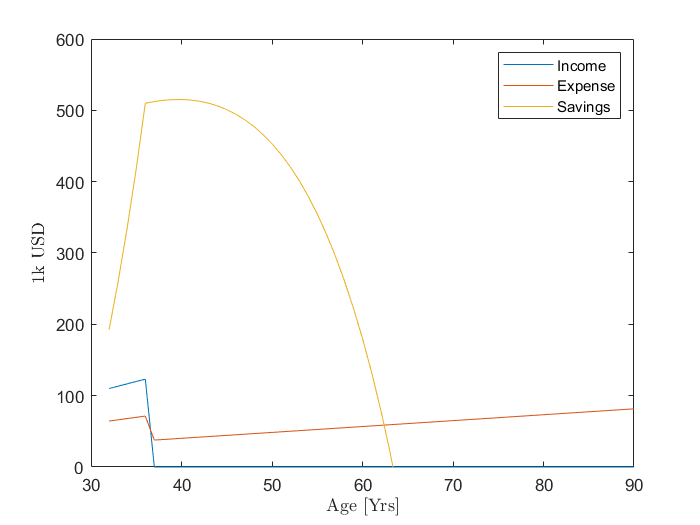

Stop_Work_Year = 5;

iSavings(1)= Initial_Savings;
for i = 1:1:100
    if i<=Stop_Work_Year
        iIncome(i) = Income*(1+(i-1)*Income_Increment_Rate/100);
        iExp(i) = 12*Expense*(1+(i-1)*Inflation/100) + (Tax/100)*iIncome(i);
    else
        iIncome(i)=0;
        iExp(i) = 12*Expense2*(1+(i-1)*Inflation/100);
    end
    
    if i==1
        iSavings(i) = iSavings(i) + iIncome(i) - iExp(i);
    else
        iSavings(i) = iSavings(i-1)+iIncome(i) - iExp(i);
    end
    iSavings_Interest(i) = ((iSavings(i))*Savings_Return_Rate/100)*(1-Capital_Gains_Tax/100);
    iSavings(i) = iSavings(i) + iSavings_Interest(i);
    if(i==30)
        iSavings(i) = iSavings(i) + parentsHome*(1+30*Inflation/100);
    end
end


figure;
years = 1:1:100;
plot(years+31,iIncome/1000);
hold on;
plot(years+31,iExp/1000);
hold on;
plot(years+31,iSavings/1000);
xlim([30,90]);
ylim([0,600]);
ylabel('1k USD');
xlabel('Age [Yrs]');
legend('Income','Expense','Savings');


[Stop_Work_Year,Years_To_Live]=calculate_retirement_possibilities(Initial_Savings,Income,Income_Increment_Rate,Expense,Inflation,Tax,Savings_Return_Rate,Capital_Gains_Tax,Expense2,parentsHome);
Inflation

Inflation = 2.4600

Tax

Tax = 28

Capital_Gains_Tax

Capital_Gains_Tax = 15

Savings_Return_Rate

Savings_Return_Rate = 10

disp(['Monthly Expense in Retirement City ',num2str(Expense2),' $'])

Monthly Expense in Retirement City 2800 $


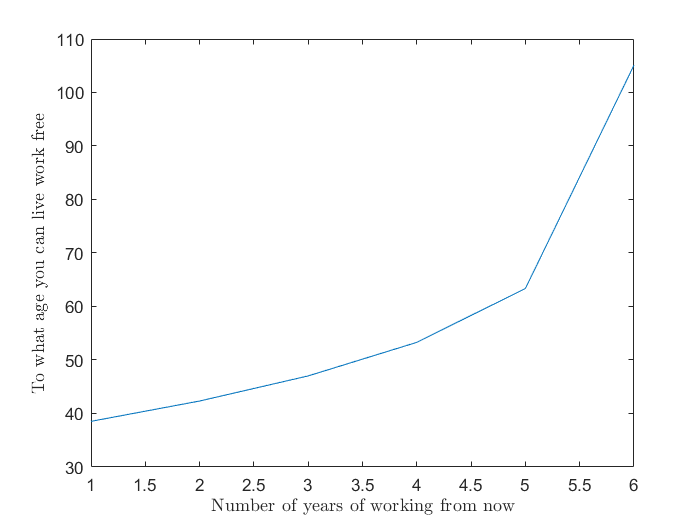

figure;
plot(Stop_Work_Year,31+Years_To_Live);
xlabel('Number of years of working from now');
ylabel('To what age you can live work free');


disp(['No of Years to Work = ',num2str(interp1(Years_To_Live(~isnan(Years_To_Live)),Stop_Work_Year(~isnan(Years_To_Live)),85-31,'linear','extrap'))]);

No of Years to Work = 5.518


## Function

function [Stop_Work_Year,Years_To_Live]=calculate_retirement_possibilities(Initial_Savings,Income,Income_Increment_Rate,Expense,Inflation,Tax,Savings_Return_Rate,Capital_Gains_Tax,Expense2,parentsHome)
    Stop_Work_Year = 1:1:50;
    years = 1:1:200;
    for k=Stop_Work_Year
    iSavings(1)= Initial_Savings;
    for i = years
        if i<=k
            iIncome(i) = Income*(1+(i-1)*Income_Increment_Rate/100);
            iExp(i) = 12*Expense*(1+(i-1)*Inflation/100) + (Tax/100)*iIncome(i);
        else
            iIncome(i)=0;
            iExp(i) = 12*Expense2*(1+(i-1)*Inflation/100);
        end
        
        if i==1
            iSavings(i) = iSavings(i) + iIncome(i) - iExp(i);
        else
            iSavings(i) = iSavings(i-1)+iIncome(i) - iExp(i);
        end
        iSavings_Interest(i) = ((iSavings(i))*Savings_Return_Rate/100)*(1-Capital_Gains_Tax/100);
        iSavings(i) = iSavings(i) + iSavings_Interest(i);
        if(i==30)
        iSavings(i) = iSavings(i) + parentsHome*(1+30*Inflation/100);
        end
    end
    
    Years_To_Live(k)=interp1(iSavings,years,0);
    end
end
    